# Laborator 3

## Problema 1

Să se genereze $N$ numere aleatoare ce urmează legea normală $N\left(\mu ,\sigma \right)$. Să se determine: 

a) distribuția statistică (cu frecvențe absolute și frecvențe relative);

b) histograma frecvențelor absolute;

c) poligonul frecvențelor absolute;

d) media aritmetică;

e) mediana;

f) modul;

g) cuartilele;

h) dispersia și abaterea standard;

i) momentele centrate de ordin 1, 2, 3 și 4.

mu = 10; sigma = 2; N = 1000;

X = random('Normal', mu, sigma, 1, N);
X = sort(X,'ascend');
X_min = min(X);
fprintf('Minimul lui X este %0f\n', X_min)

Minimul lui X este 2.515636


X_max = max(X);
fprintf('Maximul lui X este %0f\n', X_max)

Maximul lui X este 16.332506


n = fix(1 + 10/3*log10(N));
fprintf('Numarul de clase este %0f\n', n)

Numarul de clase este 11.000000


d = (X_max - X_min)/n;
fprintf('Lungimea claselor este %0f\n', d)

Lungimea claselor este 1.256079


i = 1:n+1;
c(i) = X_min + (i - 1) .* d;
[f,middle] = hist(X,n);
fprintf('Frecventele absolute ale claselor sunt: \n')

Frecventele absolute ale claselor sunt: 


fprintf('%f\n',f)

3.000000
5.000000
20.000000
90.000000
170.000000
231.000000
250.000000
144.000000
59.000000
23.000000
5.000000


fprintf('Mijloacele claselor sunt: \n')

Mijloacele claselor sunt: 


fprintf('%f\n',middle)

3.143676
4.399755
5.655834
6.911913
8.167992
9.424071
10.680150
11.936229
13.192308
14.448388
15.704467


Nr = (1:n)';
Clasa = [c(1:n)' c(2:n+1)'];
Frecventa_absoluta = f';
Mijlocul_clasei = middle';
Frecventa_relativa = f'/N;
table(Nr,Clasa,Frecventa_absoluta,Mijlocul_clasei,Frecventa_relativa)

ans = 11×5 table
    Nr         Clasa          Frecventa_absoluta    Mijlocul_clasei    Frecventa_relativa
    __    ________________    __________________    _______________    __________________

     1    2.5156    3.7717             3                3.1437               0.003       
     2    3.7717    5.0278             5                4.3998               0.005       
     3    5.0278    6.2839            20                5.6558                0.02       
     4    6.2839      7.54            90                6.9119                0.09       
     5      7.54     8.796           170                 8.168                0.17       
     6     8.796    10.052           231                9.4241               0.231       
     7    10.052    11.308           250                 10.68                0.25       
  

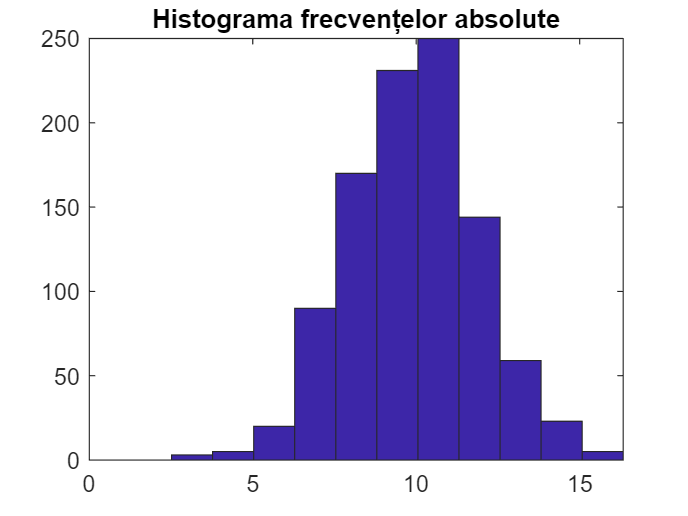

figure(1)
hist(X,n)
title('Histograma frecvențelor absolute')

med_a = mean(X);
fprintf('Media aritmetica este %0f\n', med_a)

Media aritmetica este 9.897026


med_geo = geomean(X);
fprintf('Media geometrica este %0f\n', med_geo)

Media geometrica este 9.680316


med_harm = harmmean(X);
fprintf('Media armonica este %0f\n', med_harm)

Media armonica este 9.433684


med = median(X);
fprintf('Mediana este %0f\n', med)

Mediana este 9.888505


i = f == max(f);
mod = middle(i);
fprintf('Modul este %0f\n', mod)

Modul este 10.680150


Q_1 = prctile(X,0.25);
fprintf('Cuartila inferioara este %0f\n', Q_1)

Cuartila inferioara este 2.899663


Q_2 = prctile(X,0.5);
fprintf('Mediana este %0f\n', Q_2)

Mediana este 4.730060


Q_3 = prctile(X,0.75);
fprintf('Cuartila superioara este %0f\n', Q_3)

Cuartila superioara este 4.974899


v = var(X);
fprintf('Dispersia este %0f\n', v)

Dispersia este 3.983878


s = std(X);
fprintf('Abaterea standard este %0f\n', s)

Abaterea standard este 1.995965


m1 = moment(X,1);
fprintf('Momentul de ordin 1 este %0f\n', m1)

Momentul de ordin 1 este 0.000000


m2 = moment(X,2);
fprintf('Momentul de ordin 2 este %0f\n', m2)

Momentul de ordin 2 este 3.979894


m3 = moment(X,3);
fprintf('Momentul de ordin 3 este %0f\n', m3)

Momentul de ordin 3 este -0.192363


m4 = moment(X,4);
fprintf('Momentul de ordin 4 este %0f\n', m4)

Momentul de ordin 4 este 51.215081


fprintf('\n')

## Problema 2

Să se genereze $N$ numere aleatoare ce urmează legea normală $U\left(a,b\right)$. Să se determine: 

a) distribuția statistică (cu frecvențe absolute și frecvențe relative);

b) histograma frecvențelor absolute;

c) poligonul frecvențelor absolute;

d) media aritmetică;

e) mediana;

f) modul;

g) cuartilele;

h) dispersia și abaterea standard;

i) momentele centrate de ordin 1, 2, 3 și 4.

a = 10; b = 20; N = 1000;

X = random('Uniform', a, b, 1, N);
X = sort(X,'ascend');
X_min = min(X);
fprintf('Minimul lui X este %0f\n', X_min)

Minimul lui X este 10.008086


X_max = max(X);
fprintf('Maximul lui X este %0f\n', X_max)

Maximul lui X este 19.985946


n = fix(1 + 10/3*log10(N));
fprintf('Numarul de clase este %0f\n', n)

Numarul de clase este 11.000000


d = (X_max - X_min)/n;
fprintf('Lungimea claselor este %0f\n', d)

Lungimea claselor este 0.907078


i = 1:n+1;
c(i) = X_min + (i - 1) .* d;
[f,middle] = hist(X,n);
fprintf('Frecventele absolute ale claselor sunt: \n')

Frecventele absolute ale claselor sunt: 


fprintf('%f\n',f)

88.000000
82.000000
88.000000
100.000000
89.000000
81.000000
112.000000
90.000000
84.000000
89.000000
97.000000


fprintf('Mijloacele claselor sunt: \n')

Mijloacele claselor sunt: 


fprintf('%f\n',middle)

10.461625
11.368703
12.275782
13.182860
14.089938
14.997016
15.904094
16.811172
17.718251
18.625329
19.532407


Nr = (1:n)';
Clasa = [c(1:n)' c(2:n+1)'];
Frecventa_absoluta = f';
Mijlocul_clasei = middle';
Frecventa_relativa = f'/N;
table(Nr,Clasa,Frecventa_absoluta,Mijlocul_clasei,Frecventa_relativa)

ans = 11×5 table
    Nr         Clasa          Frecventa_absoluta    Mijlocul_clasei    Frecventa_relativa
    __    ________________    __________________    _______________    __________________

     1    10.008    10.915            88                10.462               0.088       
     2    10.915    11.822            82                11.369               0.082       
     3    11.822    12.729            88                12.276               0.088       
     4    12.729    13.636           100                13.183                 0.1       
     5    13.636    14.543            89                 14.09               0.089       
     6    14.543    15.451            81                14.997               0.081       
     7    15.451    16.358           112                15.904               0.112       
  

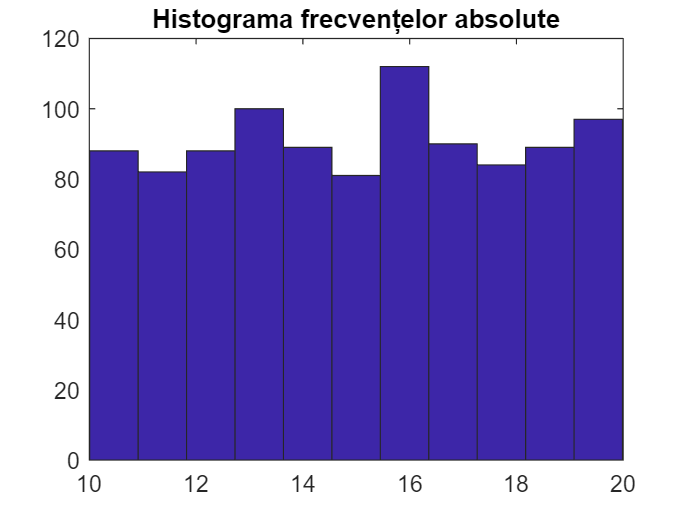

figure(1)
hist(X,n)
title('Histograma frecvențelor absolute')

med_a = mean(X);
fprintf('Media aritmetica este %0f\n', med_a)

Media aritmetica este 15.051205


med_geo = geomean(X);
fprintf('Media geometrica este %0f\n', med_geo)

Media geometrica este 14.770608


med_harm = harmmean(X);
fprintf('Media armonica este %0f\n', med_harm)

Media armonica este 14.485522


med = median(X);
fprintf('Mediana este %0f\n', med)

Mediana este 15.138204


i = f == max(f);
mod = middle(i);
fprintf('Modul este %0f\n', mod)

Modul este 15.904094


Q_1 = prctile(X,0.25);
fprintf('Cuartila inferioara este %0f\n', Q_1)

Cuartila inferioara este 10.015139


Q_2 = prctile(X,0.5);
fprintf('Mediana este %0f\n', Q_2)

Mediana este 10.048958


Q_3 = prctile(X,0.75);
fprintf('Cuartila superioara este %0f\n', Q_3)

Cuartila superioara este 10.068461


v = var(X);
fprintf('Dispersia este %0f\n', v)

Dispersia este 8.220701


s = std(X);
fprintf('Abaterea standard este %0f\n', s)

Abaterea standard este 2.867177


m1 = moment(X,1);
fprintf('Momentul de ordin 1 este %0f\n', m1)

Momentul de ordin 1 este 0.000000


m2 = moment(X,2);
fprintf('Momentul de ordin 2 este %0f\n', m2)

Momentul de ordin 2 este 8.212481


m3 = moment(X,3);
fprintf('Momentul de ordin 3 este %0f\n', m3)

Momentul de ordin 3 este -0.527354


m4 = moment(X,4);
fprintf('Momentul de ordin 4 este %0f\n', m4)

Momentul de ordin 4 este 123.444749


## Problema 3

Să se genereze $N$ numere aleatoare ce urmează legea normală $\textrm{Exp}\left(\mu \right)$. Să se determine: 

a) distribuția statistică (cu frecvențe absolute și frecvențe relative);

b) histograma frecvențelor absolute;

c) poligonul frecvențelor absolute;

d) media aritmetică;

e) mediana;

f) modul;

g) cuartilele;

h) dispersia și abaterea standard;

i) momentele centrate de ordin 1, 2, 3 și 4.

mu = 2; N = 1000;

X = random('Exponential', mu, 1, N);
X = sort(X,'ascend');
X_min = min(X);
fprintf('Minimul lui X este %0f\n', X_min)

Minimul lui X este 0.000661


X_max = max(X);
fprintf('Maximul lui X este %0f\n', X_max)

Maximul lui X este 16.503090


n = fix(1 + 10/3*log10(N));
fprintf('Numarul de clase este %0f\n', n)

Numarul de clase este 11.000000


d = (X_max - X_min)/n;
fprintf('Lungimea claselor este %0f\n', d)

Lungimea claselor este 1.500221


i = 1:n+1;
c(i) = X_min + (i - 1) .* d;
[f,middle] = hist(X,n);
fprintf('Frecventele absolute ale claselor sunt: \n')

Frecventele absolute ale claselor sunt: 


fprintf('%f\n',f)

520.000000
253.000000
116.000000
51.000000
35.000000
8.000000
11.000000
3.000000
0.000000
1.000000
2.000000


fprintf('Mijloacele claselor sunt: \n')

Mijloacele claselor sunt: 


fprintf('%f\n',middle)

0.750772
2.250993
3.751213
5.251434
6.751655
8.251876
9.752097
11.252318
12.752538
14.252759
15.752980


Nr = (1:n)';
Clasa = [c(1:n)' c(2:n+1)'];
Frecventa_absoluta = f';
Mijlocul_clasei = middle';
Frecventa_relativa = f'/N;
table(Nr,Clasa,Frecventa_absoluta,Mijlocul_clasei,Frecventa_relativa)

ans = 11×5 table
    Nr             Clasa              Frecventa_absoluta    Mijlocul_clasei    Frecventa_relativa
    __    ________________________    __________________    _______________    __________________

     1    0.00066135        1.5009           520                0.75077               0.52       
     2        1.5009        3.0011           253                  2.251              0.253       
     3        3.0011        4.5013           116                 3.7512              0.116       
     4        4.5013        6.0015            51                 5.2514              0.051       
     5        6.0015        7.5018            35                 6.7517              0.035       
     6        7.5018         9.002             8                 8.2519              0.008       
     7         9.002        

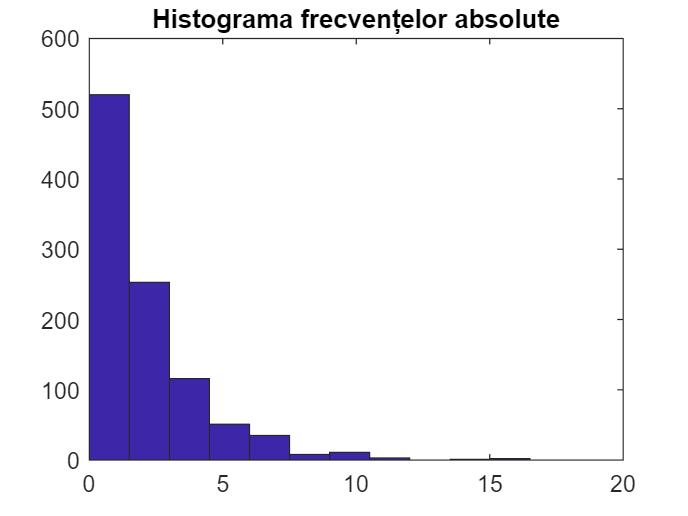

figure(1)
hist(X,n)
title('Histograma frecvențelor absolute')

med_a = mean(X);
fprintf('Media aritmetica este %0f\n', med_a)

Media aritmetica este 2.057117


med_geo = geomean(X);
fprintf('Media geometrica este %0f\n', med_geo)

Media geometrica este 1.143963


med_harm = harmmean(X);
fprintf('Media armonica este %0f\n', med_harm)

Media armonica este 0.209639


med = median(X);
fprintf('Mediana este %0f\n', med)

Mediana este 1.416924


i = find(f == max(f));
mod = middle(i);
fprintf('Modul este %0f\n', mod)

Modul este 0.750772


Q_1 = prctile(X,0.25);
fprintf('Cuartila inferioara este %0f\n', Q_1)

Cuartila inferioara este 0.007087


Q_2 = prctile(X,0.5);
fprintf('Mediana este %0f\n', Q_2)

Mediana este 0.008664


Q_3 = prctile(X,0.75);
fprintf('Cuartila superioara este %0f\n', Q_3)

Cuartila superioara este 0.011870


v = var(X);
fprintf('Dispersia este %0f\n', v)

Dispersia este 4.463297


s = std(X);
fprintf('Abaterea standard este %0f\n', s)

Abaterea standard este 2.112652


m1 = moment(X,1);
fprintf('Momentul de ordin 1 este %0f\n', m1)

Momentul de ordin 1 este 0.000000


m2 = moment(X,2);
fprintf('Momentul de ordin 2 este %0f\n', m2)

Momentul de ordin 2 este 4.458833


m3 = moment(X,3);
fprintf('Momentul de ordin 3 este %0f\n', m3)

Momentul de ordin 3 este 20.490150


m4 = moment(X,4);
fprintf('Momentul de ordin 4 este %0f\n', m4)

Momentul de ordin 4 este 200.034649
